# Object Placement

## Scenario setup

% Start the simulator
beamng =  py.beamngpy.BeamNGpy('localhost', int32(64256));
% beamng = py.beamngpy.BeamNGpy('localhost', int32(64256), home='/path/to/BeamNG.drive');

beamng.open();

% Create scenario
scenario = py.beamngpy.Scenario('west_coast_usa', 'object_placement');

% Create a vehicle
vehicle = py.beamngpy.Vehicle('ego_vehicle', pyargs('model', 'etk800', ...
                                                    'licence', 'Matlab', ...
                                                    'color', 'Green'));

scenario.add_vehicle(vehicle, pyargs('pos', py.tuple({-191.62, -160.32, 119.59}), ...
                                     'rot_quat', py.tuple({0, 0, 0.88, -0.4486})));

% Create ramp
ramp = py.beamngpy.StaticObject(pyargs('name', 'pyramp',...
                                       'pos', py.tuple({277.5, 183.5, 118.75}), ...
                                       'rot_quat', py.beamngpy.angle_to_quat(py.tuple({0, 0, 55})), ...
                                       'scale', py.tuple({1, 1, 1}), ...
                                       'shape', '/art/shapes/objects/ramp_massive.dae'));

scenario.add_object(ramp)

% Create ring
ring = py.beamngpy.ProceduralRing(pyargs('name', 'pyring', ...
                                         'pos', py.tuple({445, 301, 230}), ...
                                         'rot_quat', py.beamngpy.angle_to_quat(py.tuple({0, 0, 100})), ...
                                         'radius', 5, ...
                                         'thickness', 2.5));

scenario.add_procedural_mesh(ring)

scenario.make(beamng)
beamng.set_deterministic()
beamng.load_scenario(scenario)

tech_version = true; % Set this to False if you are running BeamNG.drive!

if tech_version
    % Setup camera
    cam_width = 2048;
    cam_height = 2048;
    cam_pos = {391.5, 251, 197.8};
    cam_dir = {445 - cam_pos{1}, 301 - cam_pos{2}, 208 - cam_pos{3}};
    cam_pos = py.tuple(cam_pos);
    cam_dir = py.tuple(cam_dir);
    cam = py.beamngpy.sensors.Camera('camera', beamng, ...
                                     pyargs('pos', cam_pos, ...
                                            'dir', cam_dir, ...
                                            'field_of_view_y', 60, ...
                                            'resolution', py.tuple({int32(cam_width), int32(cam_height)}), ...
                                            'near_far_planes', py.tuple({1, 4000}), ...
                                            'is_static', true, ...
                                            'is_visualised', false));
end

## Run simulation

beamng.start_scenario()
meshes = scenario.find_procedural_meshes();
meshes = cell(meshes);

% Find ring position
for ii = 1:length(meshes)
    mesh = meshes{ii};
    if strcmp(char(mesh.name), 'pyring')
        ring_pos = double(mesh.pos);
    end
end

% Move vehicle
for ii = 1:5
    vehicle.control(pyargs('throttle', ii/4))
    beamng.step(int32(150))
end

% Compute distance between vehicle and ring
scenario.update()
distance = norm(double(vehicle.state{'pos'}) - ring_pos);

while distance > 5
    scenario.update()
    distance = norm(double(vehicle.state{'pos'}) - ring_pos);
end

% Get camera images
if tech_version
    frames = cam.poll();
end

beamng.close()

## Plot results

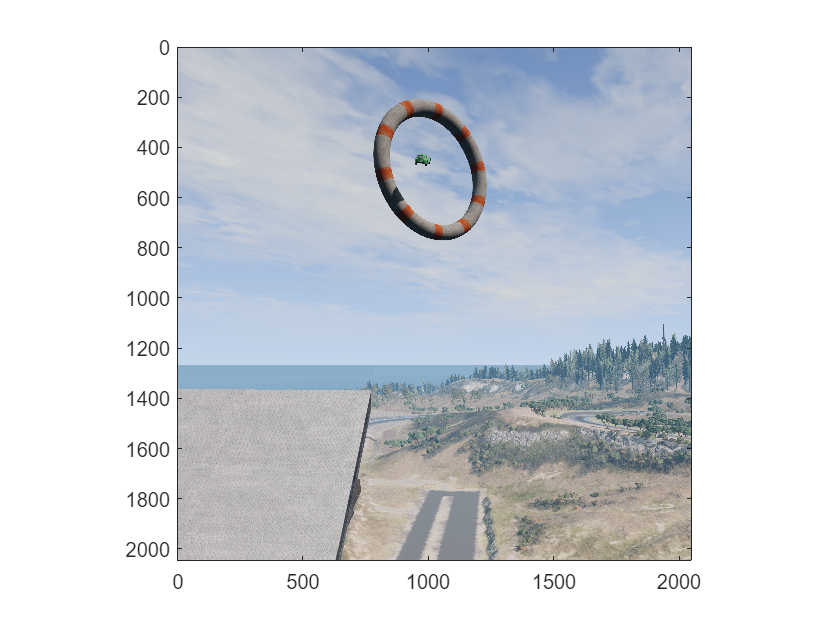

colour_RGBA = double(py.numpy.array(frames{'colour'}));
colour_RGB = colour_RGBA(:, :, 1:3) / 256;
image(colour_RGB);
axis equal
xlim([0 cam_width])
ylim([0 cam_height])